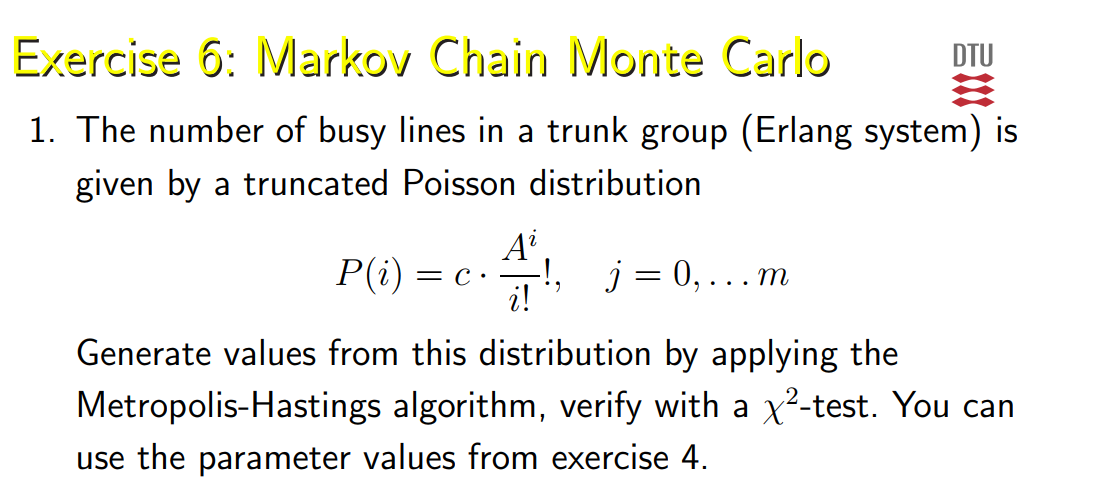

clc;clear;close all;
lambda = 1;s = 8; m = 10;
A = lambda*s;
N = 1000; %number of iterations
burn_out_period = 1e4;
%P = @(i) c*(A^i/factorial(i));
g =@(i) (A.^i./factorial(i));


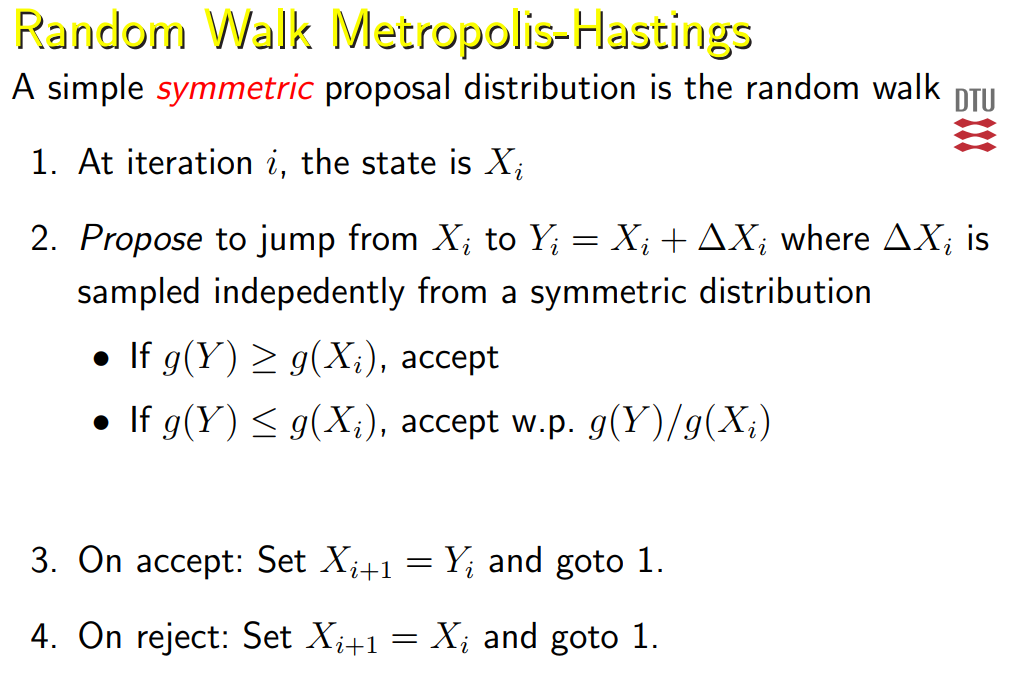

X = zeros(burn_out_period+N,1);
delta_X = zeros(N,1);
X(1) = randi(m)

X =     10
     0
     0
     0
     0
     0
     0
     0
     0
     0


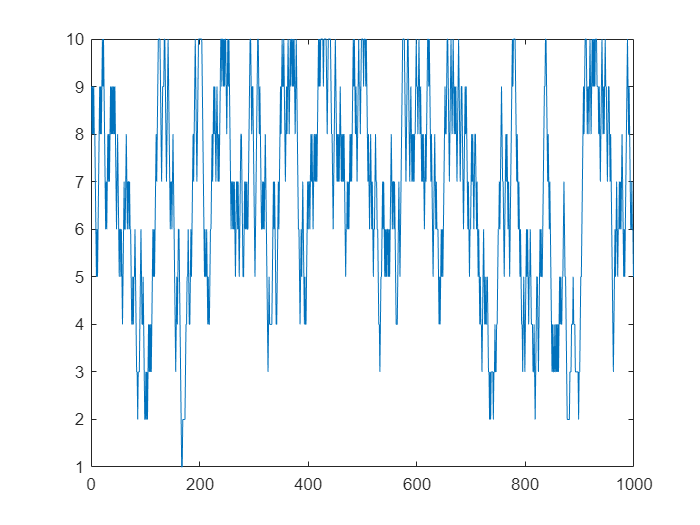

rejections = 0;
for i = 1:(burn_out_period+N)
    %delta_X(i) = round(normrnd(0,2));
    delta_X(i) = sign(randn);
    Y(i) = X(i)+delta_X(i);
    if Y(i)<0
        Y(i) = m;
    elseif Y(i)>m;
        Y(i) = 0;
    end
    if g(Y(i))>g(X(i))
        X(i+1) = Y(i);%accept
    else
        if rand()<=g(Y(i))/g(X(i))
            X(i+1) = Y(i); %accept with probability
        else 
            X(i+1) = X(i); %reject
            rejections = rejections + 1;
        end
    end
end
X = X(end-(N-1):end);
plot(1:N,X)

[n_observed2,classes] = groupcounts(X(1:5:end)); %count occurances in classes
%n_observed=histcounts(X,'BinMethod','integers');
n_observed =zeros(m+1,1);
n_observed(classes+1) =  n_observed2;
Ptrue = g(0:m)/sum(g(0:m)); %Probabilites for all observed classes
n_expected = (Ptrue'*N/5);

[pval_chi, T_chi] = chi2(n_observed,n_expected,m+1);

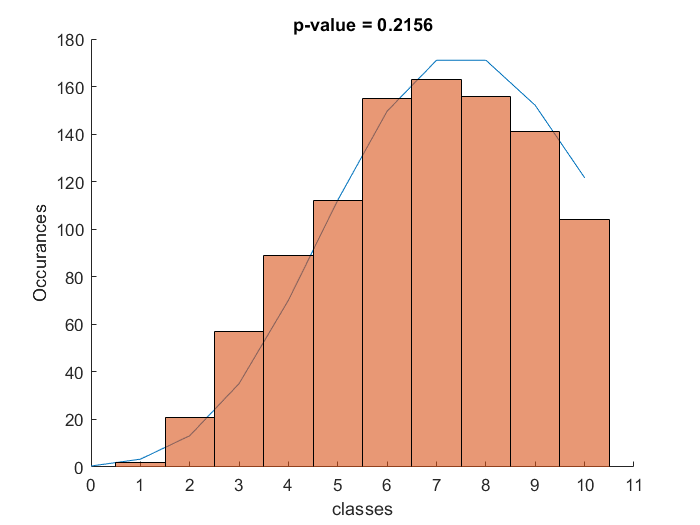

figure;
hold on
plot(0:m,Ptrue'*N)
histogram(X,'BinMethod','integers')
xlabel("classes")
ylabel("Occurances")
title('p-value = ' +string(pval_chi))
hold off

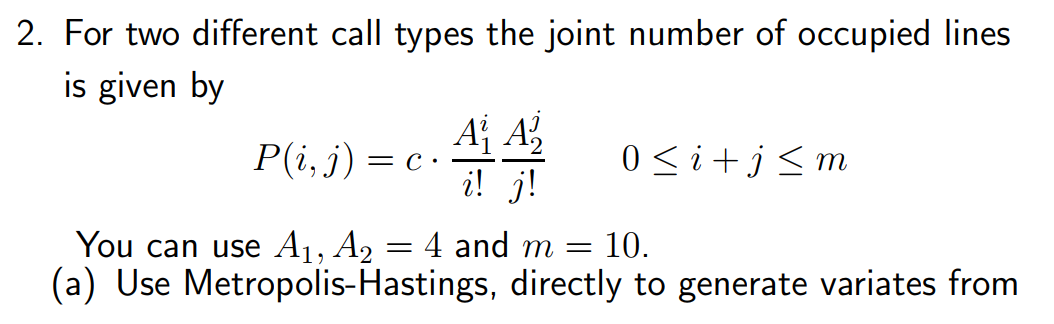this distribution

## 2 To finish with uniform probabilities around

clc;clear;close all;
A1 = 4; A2 = A1; m=10;
g =@(i,j) (A1.^i./factorial(i)).*(A2.^j./factorial(j));
N = 10000; %number of iterations

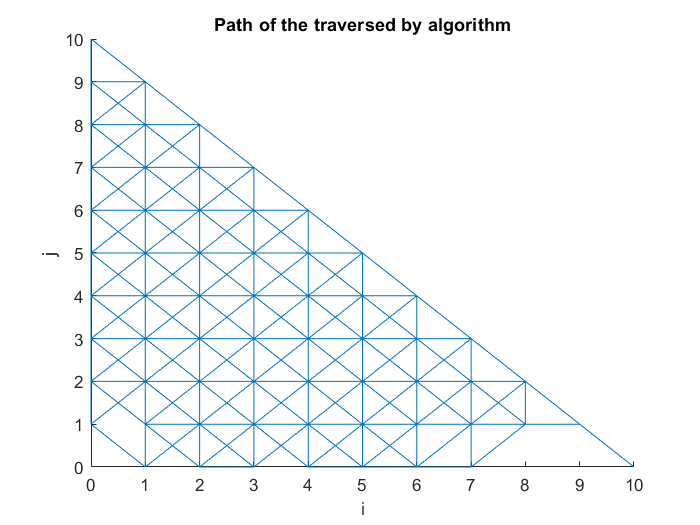

burn_out_period = 10000;
X = zeros(burn_out_period+N,2);
delta_X = zeros(N,2);
X(1) = 0;
rejections = 0;

h = tril(ones(m+1)/8,-1)+ diag([1/2,ones(1,m-1)/5,1/2]);
h(:,1) = [1/2;1/4;ones(m-2,1)/5;1/3];
h(end,:) =[1/3,ones(1,m-2)/5,1/4,1/2];
h = ones(m+1);
for i = 1:(burn_out_period+N)

    y = [-1,-1];
    while sum(y)>m || any(y<0)
        r = randi(9)-1;
        delta_X(i,:) = [round(sin(2*pi*r/8)),round(cos(2*pi*r/8))];
        y = X(i,:)+delta_X(i,:);  
    end
    Y(i,:) = y;
    if g(Y(i,1),Y(i,2))*h(Y(i,1)+1,Y(i,2)+1)>g(X(i,1),X(i,2))*h(X(i,1)+1,X(i,2)+1)
        X(i+1,:) = Y(i,:);%accept
    else
        if rand()<=g(Y(i,1),Y(i,2))*h(Y(i,1)+1,Y(i,2)+1)/g(X(i,1),X(i,2))*h(X(i,1)+1,X(i,2)+1)
            X(i+1,:) = Y(i,:); %accept with probability
        else 
            X(i+1,:) = X(i,:); %reject
            rejections = rejections + 1;
        end
    end
end

X = X(end-(N-1):end,:);

hold on
title('Path of the traversed by algorithm')
xlabel("i")
ylabel("j")
plot(X(:,1),X(:,2))
hold off

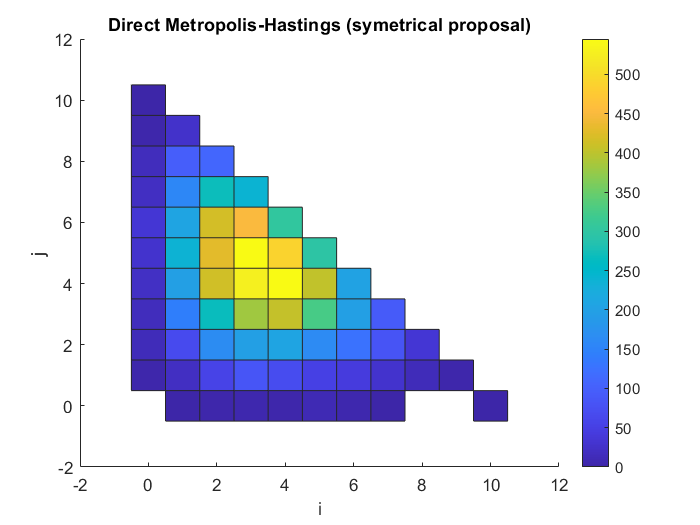

%saveas(gcf,'ex6_2_a_path_sym.png')
P_true = zeros(m+1,m+1);
classes = 0;
%%%%%%%%%%%%%%%%Get probability dist%%%%%%%%%%
for i = 0:m
    for j = 0:(m-i)
        P_true(i+1,j+1) = g(i,j);
        classes = classes+1;
    end
end
P_true = P_true/sum(P_true,'all');

%%%%%%Chi2 test%%%%%
% [n_observed,classes] = groupcounts(X);
% classes = cell2mat(classes)+1;
% for i = 1:length(classes)
%         n_expected(i,1) = P_true(classes(i,1),classes(i,2));
% end
figure;
hold on
xlabel("i")
ylabel("j")
title("Direct Metropolis-Hastings (symetrical proposal)")
h = histogram2(X(:,1),X(:,2),[(-0.5):1:(m+0.5)],[(-0.5):1:m+(0.5)],'DisplayStyle','tile','ShowEmptyBins','off');
colorbar
hold off
saveas(gcf,'ex6_2_a_histogram_sym.png')

n_observed=h.Values;
n_expected = P_true*N;
n_observed = n_observed(n_expected>0);
n_expected = n_expected(n_expected>0);

[pval, T] = chi2(n_observed,n_expected,length(n_expected))

pval =      0


T =      2.564582976175383e+03


figure;
imagesc(P_true*N)
colorbar
title("True distribution")
saveas(gcf,'ex6_2_a_true.png')

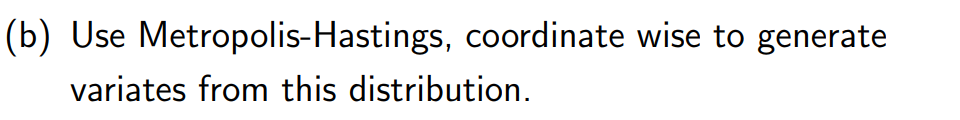

clc;clear;close all;
A1 = 4; A2 = A1; m=10;
g =@(i,j) (A1.^i./factorial(i)).*(A2.^j./factorial(j));
N = 10000; %number of iterations

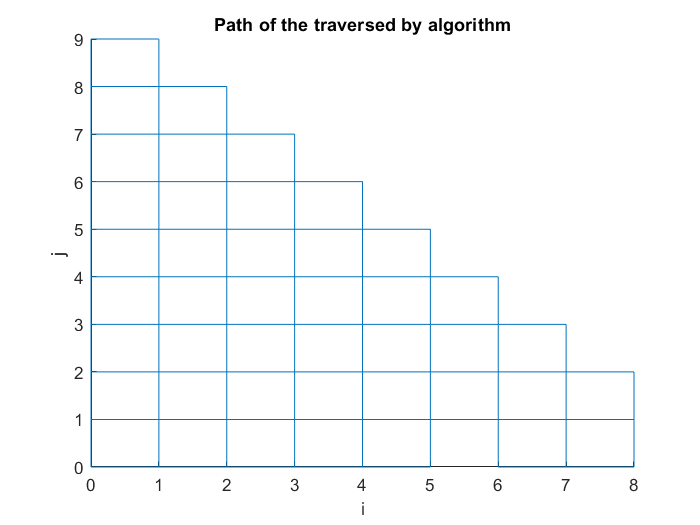

burn_out_period = 1000;
X = zeros(burn_out_period+N,2);
delta_X = zeros(N,2);
X(1) = 0;
rejections = 0;
h = tril(ones(m+1)/4)+ diag([3/4,ones(1,m-1)/4,3/4]);
h(:,1)= [1;ones(m-1,1)/3;1/2];
h(end,:)= [1,ones(1,m-1)/3,1];
h = ones(m+1);
for i = 1:(burn_out_period+N)
    
    y=[-10,100];
    while sum(y)>m || any(y<0)
         dirct = mod(i,2); %systematic
         delta_X(i,:) = [sign(randn)*dirct,sign(randn)*(1-dirct)];
         y = X(i,:)+delta_X(i,:);
    end

    Y(i,:) = y;

    
    if g(Y(i,1),Y(i,2))*h(Y(i,1)+1,Y(i,2)+1)>g(X(i,1),X(i,2))*h(X(i,1)+1,X(i,2)+1)
        X(i+1,:) = Y(i,:);%accept
    else
        if rand()<=g(Y(i,1),Y(i,2))*h(Y(i,1)+1,Y(i,2)+1)/g(X(i,1),X(i,2))*h(X(i,1)+1,X(i,2)+1)
            X(i+1,:) = Y(i,:); %accept with probability
        else 
            X(i+1,:) = X(i,:); %reject
            rejections = rejections + 1;
        end
    end
end

X = X(end-(N-1):end,:);

hold on
title('Path of the traversed by algorithm')
xlabel("i")
ylabel("j")
plot(X(:,1),X(:,2))
hold off
saveas(gcf,'ex6_2_b_path_sym.png')

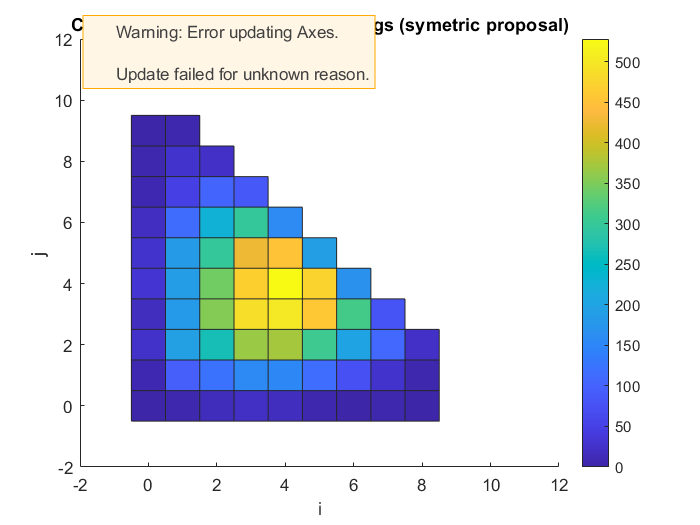

P_true = zeros(m+1,m+1);
classes = 0;
%%%%%%%%%%%%%%%%Get probability dist%%%%%%%%%%
for i = 0:m
    for j = 0:(m-i)
        P_true(i+1,j+1) = g(i,j);
        classes = classes+1;
    end
end
P_true = P_true/sum(P_true,'all');

%%%%%%Chi2 test%%%%%
% [n_observed,classes] = groupcounts(X);
% classes = cell2mat(classes)+1;
% for i = 1:length(classes)
%         n_expected(i,1) = P_true(classes(i,1),classes(i,2));
% end
figure;
hold on
xlabel("i")
ylabel("j")
title("Coordinate-wise Metropolis-Hastings (symetric proposal)")
h = histogram2(X(:,1),X(:,2),[(-0.5):1:(m+0.5)],[(-0.5):1:m+(0.5)],'DisplayStyle','tile','ShowEmptyBins','off');
colorbar
hold off
saveas(gcf,'ex6_2_b_histogram_sym.png')

n_observed=h.Values;
n_expected = P_true*N;
n_observed = n_observed(n_expected>0);
n_expected = n_expected(n_expected>0);

[pval, T] = chi2(n_observed,n_expected/5,length(n_expected))

pval =      0


T =      3.481116267536191e+04
